# **INICIALIZACAO**

clear all
close all
clc

m = 1.0;
M = 5.0;
L = 2.0;
g = -10.0;
d = 1.0;

s = 1; % Pendulum up (s=1)‍

A = [0          1                0 0;
     0       -d/M           -m*g/M 0;
     0          0                0 1;
     0 -s*d/(M*L) -s*(m+M)*g/(M*L) 0];

B = [0; 1/M; 0; s*1/(M*L)];

C = [1,0,0,0];

D = zeros(size(C,1), size(B,2));

# **AUTOVALORES**

eig(A)

ans =          0
   -2.4674
   -0.1665
    2.4339


# **CONTROLABILIDADE**

rank(ctrb(A,B))

ans = 4

# **LQR**

Q = diag([100,100,10,100]);
R = 0.00001;
K = lqr(A,B,Q,R);
K'

ans = 	1.0e+04 *

   -0.3162
   -0.6071
    4.2510
    1.9262


# **FILTRO DE KALMAN**

Vd = 0.001*eye(4); % disturance covariance
Vn = 0.001;        % noise covariance

[L,P,E] = lqe(A,Vd,C,Vd,Vn);
Kf      = (lqr(A',C',Vd,Vn))';

sysKF   = ss(A-Kf*C, [B Kf], eye(4), 0*[B Kf]);

# **Simulação**

x = $\left[\matrix{x & \dot{x} & \theta & \dot{\theta}} \right]^T$

tspan = 0:.001:15;

x0 = [-1; 0; pi+.4; 0]; % initial condition
wr = [0; 0; pi; 0]; % reference position
% u  =@(tt, xx) fn_controle(tt,xx,K,wr);
u  =@(xx) -K*(xx - wr);

[t,x] = ode45(@(t,x)fn_eq_diferencial(x,m,M,L,g,d,u(x)),tspan,x0);

# **ANIMACAO**

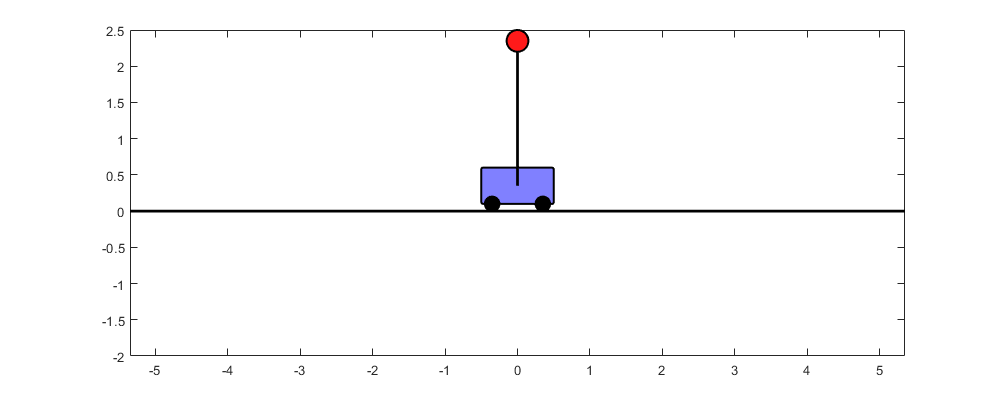

passo = 200;
fn_animacao_carro(t, x, m, M, L, passo);

# **GRAFICO ESTADOS**

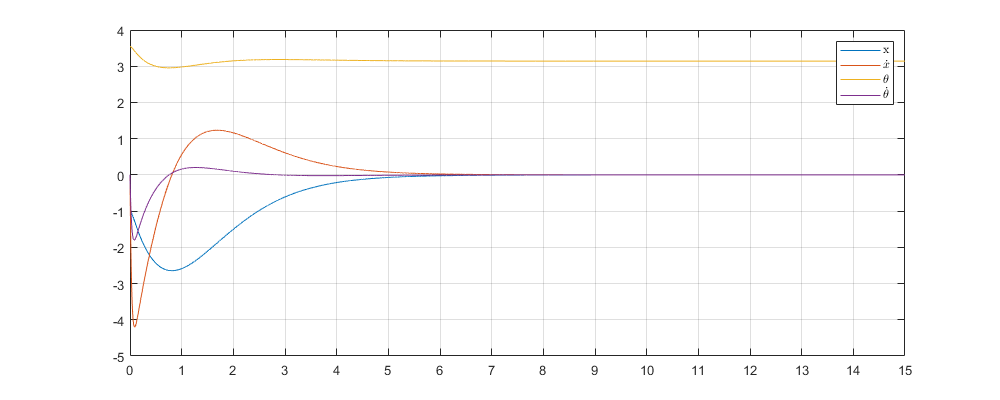

h = plot(t,x); 

leg = legend('x', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(leg,'Interpreter','latex');
grid on;
h(1).Parent.XTick = [0:1:15];